# Technical Note on Data Processing

This note documents the processing procedures for dorsal root ganglion discharge data collected from AA rat models before and after acupuncture stimulation. The corresponding article is titled "Acupuncture-Induced Dorsal Root Potentials and Mast Cell Degranulation in AA Rats."

## 1. Original data

The experimental methods and data acquisition procedures are detailed in the original article. Here, we provide pre-processed and cleaned raw data (note: pre-processing primarily involved removing irrelevant redundant data from the experimental process and performing temporal alignment). The data is located in the "source_data" folder, which contains three subfolders: "acu", "saline", and "dscg". Each subfolder contains neural electrical signal data stored in files named "animal_{xx}.mat".

Each data recording spans 45 minutes, comprising baseline (10 min), stabilization (15 min), acupuncture (10 min), and recovery (10 min) phases. The sampling rate is 20 kHz.

The following code plots a time-domain data.

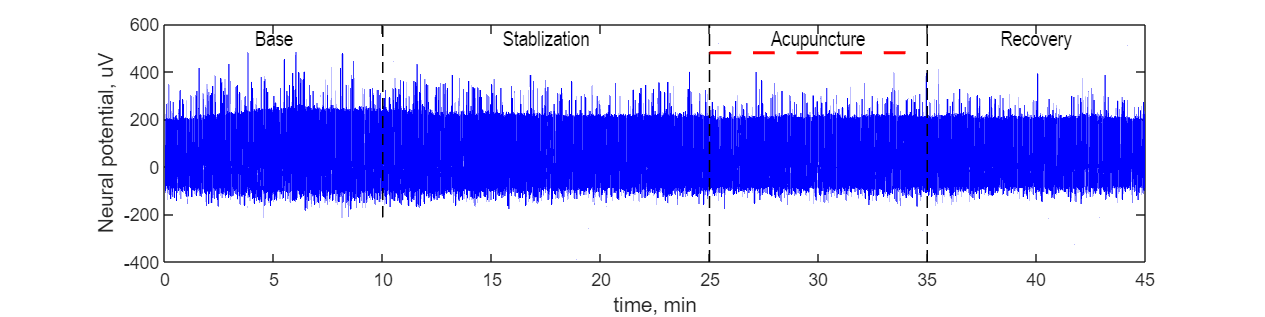

close all; clearvars; clc;
datafile = './source_data/ACU1.mat'; % AUTHORS: please alter here to plot different results
% 
load(datafile); % the result is stored as variable 'data'
fs = 20000;
x = 1e6*data; t = [0:length(x)-1]/fs/60; % time in minutes, voltage in uV
figure(1); set(gcf,'position',[0,0,1200,300]);
plot(t(1:20:end),x(1:20:end),'b-','linewidth',1); hold on; % to reduce ploting efforts, plot every 20 points (0.01s)
set(gca,'fontsize',12);
for(ii = [10,25,35]) plot([ii,ii],get(gca,'ylim'),'k--','linewidth',1); hold on; end
loc = get(gca,'ylim'); loc2 = loc(2);
for(ii = 1:2:10) plot([25+ii-1,25+ii],0.8*loc2+[0,0],'r-','linewidth',2); end
xloc = [5,17.5,30,40]; anno = {'Base','Stablization','Acupuncture','Recovery'};
for ii = 1:length(xloc)
    text(xloc(ii),0.9*loc2,anno{ii},'fontname','arial narrow','fontsize',14, 'HorizontalAlignment','center');
end
xlabel('time, min', 'FontSize',14); ylabel('Neural potential, uV','FontSize',14);

## 2. Calculate the firing rate 

### 2.1 Detecting neural spikes

To calculate neuronal firing rates, it is first necessary to detect neural impulses (spikes). Although more advanced and sophisticated detection methods exist, we employ a simple and rapid approach here, based on the following facts:

- Neuronal discharges form a relatively high positive potential.

- Neurons have a refractory period after firing.

Accordingly, the `fun_detect_spikes_original` function detects neuronal discharges based on time-domain data. This function has two parameters: first, the threshold (voltages above this value are considered neuronal discharges, set at 50μV in this study); second, the refractory period (only one neuronal discharge can occur within the same refractory period, set at 4ms in this study). These two parameters may have minor quantitative effects on the results of this study, but they essentially do not affect the qualitative outcomes.

### 2.2 Calculation of Firing Rate

Firing rate is defined as the number of neural impulses per unit time. We processed the entire 45-minute dataset using a 10-second sliding window (with no overlap between consecutive windows), resulting in 270 firing rate values. This calculation is implemented in the `fun_calc_fr` function.

### 2.3 Batch Processing

The following code performs batch analysis on the data from each group of animals and stores the firing rate results for each group in a corresponding `FR_original.mat` file within their respective subfolders.

% AUTHORS: this code section may take a while, please be patient. ;p
close all; clearvars; clc;
folders = {'ACU','SALINE','DSCG'}; fs = 20000;
for i = 1:length(folders)
    folder = folders{i};
    SpikeLoc = {}; FR = []; 
    for animal = 1:7
        filename = sprintf('./source_data/%s%d.mat',folder,animal);
        load(filename); % to get data 
        [spikeloc, spikevol] = fun_detect_spikes(data,50e-6,5e-3*fs); 
        data = data*0; data(spikeloc) = 1; 
        fr = fun_calc_fr(data,10,fs);
        SpikeLoc{animal} = spikeloc; 
        FR(animal,:) = fr;
    end
    savefile = sprintf('./source_data/%s_FR_original.mat',folder);
    save(savefile,'SpikeLoc','FR'); 
end

## 3. Statistics and Visualization

### 3.1 Statistics on Firing Rate 

First, calculate the average firing rate (f) for each animal across different stages (baseline, stabilization, acupuncture, recovery). Then, compute the mean and standard error of these firing rates. Finally, use repeated measures ANOVA (rmANOVA) to assess differences between the stages. The result will be stored in `FR_statistics.mat`, the following code deals with the statistics. 

format compact
format short
folders = {'ACU','SALINE','DSCG'};
for kk = 1:length(folders)
    folder = folders{kk};
    fprintf(1,'%s \n',repmat('#',1,100));
    fprintf(1,' ANALYSISING %s\n',folder);
    fprintf(1,'%s \n',repmat('#',1,100));
    FRfile = sprintf('./source_data/%s_FR_original.mat',folder);
    load(FRfile);
    window_in_seconds = 10; % FR data is calculated every 10 seconds  
    timepoints = [10,15,10,10]; % duration of the stages, in min
    timepoints = [cumsum(timepoints)]; 
    timepoints = timepoints*60/10;
    FRacuperiod = FR(:,timepoints(2)+1:timepoints(3));
    FRtwist = FRacuperiod(:,[ 1:6,13:18,25:30,37:42,49:54]);
    FRretain= FRacuperiod(:,[7:12,19:24,31:36,43:48,55:60]);
    FRbase = mean( FR(:,1:timepoints(1)), 2 );
    FRstab = mean( FR(:,timepoints(1)+1:timepoints(2)), 2 );
    FRtwis = mean( FRtwist, 2 );
    FRreta = mean( FRretain,2 );
    FRreco = mean( FR(:,timepoints(3)+1:end), 2 );
    FRtable = array2table( [FRbase,FRstab,FRtwis,FRreta,FRreco],'VariableNames',{'f_base','f_stab','f_twist','f_retain','f_reco'} );
    fprintf(1,'Table. Neural discharge frequency for each animal, divided by time stages\n')
    disp(FRtable);
    fprintf(1,'%s \n',repmat('-',1,30));
    % statistics
    means = mean(FRtable{:,:});      % average 
    stds = std(FRtable{:,:});        % standard deviation
    stderrs = stds / sqrt(height(FRtable));  % standard error
    statsTable = table(means', stds', stderrs', ...
        'VariableNames', {'mean', 's.d.', 's.e.'}, ...
        'RowNames', FRtable.Properties.VariableNames);
    fprintf(1,'Table. mean, std and se results\n')
    disp(statsTable); fprintf(1,'%s \n',repmat('-',1,30));
    % rm-ANOVA and post-hoc comparisons
    withinDesign = table([1 2 3 4 5]', 'VariableNames', {'Stage'});
    withinDesign.Properties.Description = 'Within-subject factor: Stage';
    rm = fitrm(FRtable, 'f_base-f_reco ~ 1', 'WithinDesign', withinDesign);
    ranovaResults = ranova(rm);
    fprintf(1,'Result. RM-ANOVA report\n')
    disp(ranovaResults);
    fprintf(1,'%s \n',repmat('-',1,30));
    % Post-hoc comparisons 
    multcompareResults = multcompare(rm, 'Stage');
    fprintf(1,'Result. Post-hoc comp. report\n');
    disp(multcompareResults);
end

#################################################################################################### 


 ANALYSISING ACU


#################################################################################################### 


Table. Neural discharge frequency for each animal, divided by time stages


    f_base    f_stab    f_twist    f_retain    f_reco
    ______    ______    _______    ________    ______
    75.028    73.139     76.15       72.34     73.108
    29.912    32.433     43.26      39.417     41.922
    42.838    42.171    56.623       42.97     44.643
     11.99    14.063    24.107      19.657     19.613
    17.507    17.002    27.397      18.677     18.593
    23.865    21.998    25.937      22.547      21.12
    35.393    33.933    42.133      37.173     38.883


------------------------------ 


Table. mean, std and se results


                 mean      s.d.      s.e. 
                ______    ______    ______
    f_base       33.79    20.972    7.9267
    f_stab      33.534    20.125    7.6064
    f_twist      42.23     19.03    7.1925
    f_retain    36.111    18.843     7.122
    f_reco       36.84    19.507    7.3729
------------------------------ 


Result. RM-ANOVA report


                         SumSq     DF    MeanSq      F         pValue      pValueGG      pValueHF     pValueLB
                         ______    __    ______    ______    __________    _________    __________    ________
    (Intercept):Stage    344.62     4    86.155    11.763    1.9732e-05    0.0019813    0.00033339    0.013975
    Error(Stage)         175.78    24     7.324                                                               


------------------------------ 


Result. Post-hoc comp. report


    Stage_1    Stage_2    Difference    StdErr      pValue       Lower      Upper  
    _______    _______    __________    _______    _________    _______    ________
       1          2         0.25619     0.69154      0.99488    -2.3379      2.8503
       1          3          -8.439      1.9838     0.029152     -15.88    -0.99767
       1          4          -2.321      1.7247       0.6776    -8.7906      4.1487
       1          5           -3.05      1.9825       0.5771    -10.487      4.3867
       2          1        -0.25619     0.69154      0.99488    -2.8503      2.3379
       2          3         -8.6952      1.5242    0.0072145    -14.413     -2.9779
       2          4         -2.5771      1.0739      0.23417    -6.6056      1.4513
      

#################################################################################################### 


 ANALYSISING SALINE


#################################################################################################### 


Table. Neural discharge frequency for each animal, divided by time stages


    f_base    f_stab    f_twist    f_retain    f_reco
    ______    ______    _______    ________    ______
    16.435    18.789    23.297       19.46     18.442
    24.085    22.557    28.233      25.713     23.267
    11.473    11.466     18.95      12.763     11.972
    16.998    17.887    33.663      19.743     19.897
    21.787    21.296    24.613      21.003      20.04
    52.608    52.258    55.227      50.293     49.343
      43.2    44.516     50.35      44.453      43.93


------------------------------ 


Table. mean, std and se results


                 mean      s.d.      s.e. 
                ______    ______    ______
    f_base      26.655    15.307    5.7855
    f_stab      26.967    15.214    5.7504
    f_twist     33.476    14.015    5.2972
    f_retain    27.633    14.108    5.3323
    f_reco      26.699    14.125    5.3389
------------------------------ 


Result. RM-ANOVA report


                         SumSq     DF    MeanSq      F         pValue      pValueGG     pValueHF     pValueLB 
                         ______    __    ______    ______    __________    _________    _________    _________
    (Intercept):Stage    239.99     4    59.998    14.539    3.6672e-06    0.0034524    0.0017699    0.0088325
    Error(Stage)         99.041    24    4.1267                                                               


------------------------------ 


Result. Post-hoc comp. report


    Stage_1    Stage_2    Difference    StdErr      pValue       Lower        Upper  
    _______    _______    __________    _______    _________    ________    _________
       1          2        -0.31143     0.48994      0.96334     -2.1492       1.5264
       1          3          -6.821       1.814     0.049505     -13.625    -0.016429
       1          4        -0.97762     0.72135       0.6726     -3.6835       1.7283
       1          5       -0.043333     0.81029            1     -3.0828       2.9962
       2          1         0.31143     0.48994      0.96334     -1.5264       2.1492
       2          3         -6.5095      1.6526     0.040748     -12.709      -0.3103
       2          4        -0.66619     0.62465      0.81728     -3.0093  

#################################################################################################### 


 ANALYSISING DSCG


#################################################################################################### 


Table. Neural discharge frequency for each animal, divided by time stages


    f_base    f_stab    f_twist    f_retain    f_reco
    ______    ______    _______    ________    ______
    17.732     17.45    19.197      18.767     16.997
    23.667    25.538    24.627      24.297      24.34
    28.408    28.237    32.607      34.387     38.883
    37.102     32.66     32.35      30.123     30.397
    35.698    37.724    38.813      36.253     35.487
    20.543    17.132    23.777      16.867     16.445
     18.42    19.458    22.443       18.82     17.535


------------------------------ 


Table. mean, std and se results


                 mean      s.d.      s.e. 
                ______    ______    ______
    f_base      25.939    8.0012    3.0242
    f_stab      25.457    7.9531     3.006
    f_twist     27.688    6.9998    2.6457
    f_retain    25.645    7.9768     3.015
    f_reco      25.726    9.3234    3.5239
------------------------------ 


Result. RM-ANOVA report


                         SumSq     DF    MeanSq       F       pValue     pValueGG    pValueHF    pValueLB
                         ______    __    ______    _______    _______    ________    ________    ________
    (Intercept):Stage    23.146     4    5.7866    0.89858    0.48024    0.42627     0.45092     0.37976 
    Error(Stage)         154.55    24    6.4397                                                          


------------------------------ 


Result. Post-hoc comp. report


    Stage_1    Stage_2    Difference    StdErr     pValue      Lower     Upper 
    _______    _______    __________    _______    _______    _______    ______
       1          2         0.48159     0.95783    0.98403    -3.1114    4.0745
       1          3          -1.749      1.1772     0.6043    -6.1648    2.6667
       1          4         0.29381      1.5375    0.99961    -5.4736    6.0613
       1          5         0.21238      2.0295    0.99996    -7.4004    7.8251
       2          1        -0.48159     0.95783    0.98403    -4.0745    3.1114
       2          3         -2.2306      1.0058     0.2877    -6.0037    1.5424
       2          4        -0.18778      1.0903    0.99974    -4.2776     3.902
       2          5        -0.26921      1

### 3.2 Plot time-frequency curve 

To eliminate individual differences in f_base, we used the normalized frequency f/f_base as the plotting metric to illustrate the changes in neural firing rates throughout the experimental process for each group of animals. This was achieved through the following code.

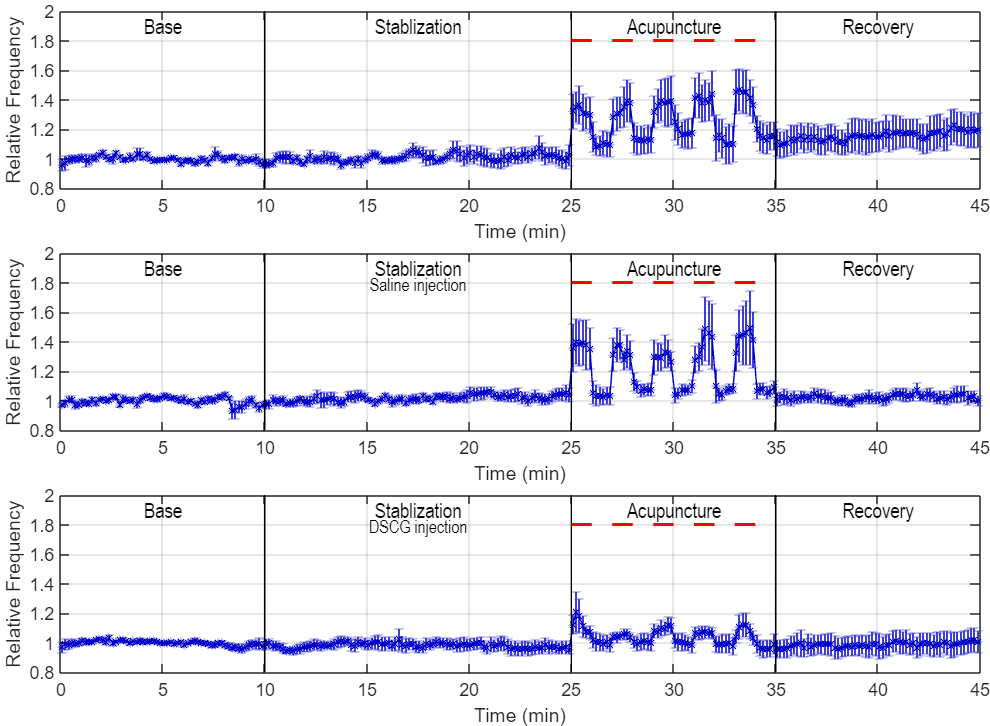

folders = {'acu','saline','dscg'}; % change the folder name for analysis of different groups, i.e. acu, saline, or dscg
fig = figure(1); clf; set(gcf,'position',[0,0,900,220*length(folders)]);
tiledlayout(length(folders),1,"TileSpacing","tight","Padding","tight");
for k = 1:length(folders)
    nexttile(k);
    folder = folders{k};
    FRfile = sprintf('./source_data/%s_FR_original.mat',folder);
    load(FRfile); [n,nT] = size(FR); FRnorm = FR; 
    FRbase = mean( FR(:,1:60),2 ); 
    for i = 1:n 
        FRnorm(i,:) = FRnorm(i,:)/FRbase(i);
    end
    mean_FRnorm = mean(FRnorm); 
    std_FRnorm = std(FRnorm); se_FRnorm = std_FRnorm/sqrt(n);
    t = ( 5+(0:length(mean_FRnorm)-1)*10 )/60; % in minutes
    
    errorbar(t,mean_FRnorm,se_FRnorm,'*-','color',[0,0,0.8]);
    set(gca,'xlim',[0,45],'ylim',[0.8,2.0],'fontsize',12); 
    xlabel('Time (min)'); ylabel('Relative Frequency'); grid on; hold on;
    for ii = [10,25,35]
        plot([ii,ii],get(gca,'ylim'),'k-','linewidth',1);
    end
    xloc = [5,17.5,30,40]; yloc = 1.9; anno = {'Base','Stablization','Acupuncture','Recovery'};
    anno2 = {'','Saline injection','DSCG injection'};
    for ii = 1:2:10
        plot([25+ii-1,25+ii],1.8+[0,0],'r-','linewidth',2);
    end
    for ii = 1:length(xloc)
        text(xloc(ii),yloc,anno{ii},'fontname','arial narrow','fontsize',14,...
            'HorizontalAlignment','center','color','k');
        if ii == 2
            text(xloc(ii),yloc-0.11,anno2{k},'fontname','arial narrow','fontsize',12,...
            'HorizontalAlignment','center','color','k');
        end
    end
    set(gca,'fontsize',12,'ytick',[0.8:0.2:2]);
end

## 4. Twisting vs. Retaining 

Here, we compare the differences in neural discharge rates between the twisting phase and the retaining phase (five each) during the acupuncture stage and plot a comparison chart.

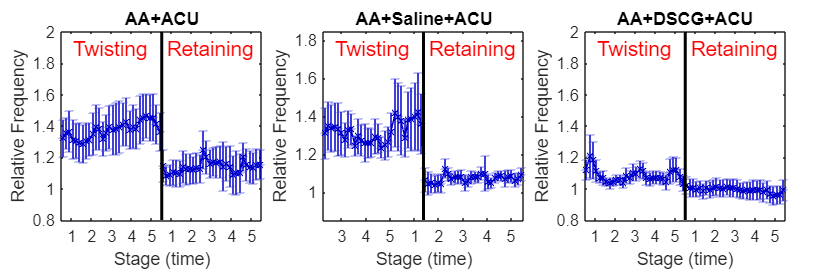

folders = {'ACU','SALINE','DSCG'};
titles = {'AA+ACU','AA+Saline+ACU','AA+DSCG+ACU'};
fig = figure(1); clf; set(gcf,'position',[0,0,250*length(folders),250]);
tiledlayout(1,length(folders),"TileSpacing","compact","Padding","compact");
for k = 1:length(folders)
    nexttile(k);
    folder = folders{k};
    FRfile = sprintf('./source_data/%s_FR_original.mat',folder);
    load(FRfile); FRnorm = FR; FRbase = mean( FR(:,1:60),2 ); 
    [n,nT] = size(FR);
    for i = 1:n 
        FRnorm(i,:) = FRnorm(i,:)/FRbase(i);
    end
    % 
    idx = 150+[1:60]; idx = reshape(idx,6,10);
    idx_twist = idx(:,1:2:end); idx_retain= idx(:,2:2:end);
    FRtwist = FR(:,idx_twist(:)); FRretain= FR(:,idx_retain(:)); 
    FRtwist_norm = FRnorm(:,idx_twist(:)); FRretain_norm = FRnorm(:,idx_retain(:));
    t = 1:60;
    y = [FRtwist_norm, FRretain_norm];
    mean_y = mean(y); 
    std_y = std(y); se_y = std_y/sqrt(n);
    errorbar(t,mean_y,se_y,'*-','color',[0,0,0.8]); hold on;
    set(gca,'xlim',[0.5,60.5],'ylim',[0.8,2],'fontsize',10); 
    xlabel('Stage (time)', 'FontSize',11); ylabel('Relative Frequency','fontsize',11);
    title(titles{k});
    plot([30.5,30.5],[0.8,2],'k-','linewidth',2);
    text( 15,1.9,'Twisting', 'FontSize',14,'HorizontalAlignment','center','color','r' );
    text( 45,1.9,'Retaining','FontSize',14,'HorizontalAlignment','center','color','r' );
    set(gca,'xtick',[3.5:6:60],'xticklabel',[1 2 3 4 5 1 2 3 4 5],'ytick',[0.8:0.2:2.0]);
    set(gca,'fontsize',11);
end

For statistical analysis, we will employ the following averaging procedures on either the firing rate (FR) or normalized firing rate (FRnorm) data. Average data across the 6 timepoints for each animal to obtain a single value per subject, then average these values across the 7 animals in the group.

folders = {'ACU','SALINE','DSCG'};
for kk = 1:length(folders)
    folder = folders{kk};
    fprintf(1,'%s \n',repmat('#',1,100));
    fprintf(1,' ANALYSISING %s\n',folder);
    fprintf(1,'%s \n',repmat('#',1,100));
    FRfile = sprintf('./source_data/%s_FR_original.mat',folder);
    load(FRfile); FRnorm = FR; FRbase = mean( FR(:,1:60),2 ); 
    [n,nT] = size(FR);
    for i = 1:n 
        FRnorm(i,:) = FRnorm(i,:)/FRbase(i);
    end
    % 
    idx = 150+[1:60]; idx = reshape(idx,6,10);
    idx_twist = idx(:,1:2:end); idx_retain= idx(:,2:2:end);
    FRtwist = FR(:,idx_twist(:)); FRretain= FR(:,idx_retain(:)); 
    FRtwist_norm = FRnorm(:,idx_twist(:)); FRretain_norm = FRnorm(:,idx_retain(:));
    % statistics
    [FRtwist_mean, FRtwist_se, FRretain_mean, FRretain_se] = deal(zeros(5,1));
    [FRtwist_n_mean, FRtwist_n_se, FRretain_n_mean, FRretain_n_se] = deal(zeros(5,1));
    for i = 1:5
        twist_i = 6*(i-1)+[1:6]; retain_i = 6*(i-1)+[1:6];
        FRtwist_i = FRtwist(:,twist_i); FRtwist_norm_i = FRtwist_norm(:,twist_i);
        FRretain_i = FRretain(:,retain_i); FRretain_norm_i = FRretain_norm(:,retain_i);
        [m,sd,se] = fun_mean_se(FRtwist_i,2);  FRtwist_mean(i)=m;  FRtwist_se(i) = se;
        [m,sd,se] = fun_mean_se(FRretain_i,2); FRretain_mean(i)=m; FRretain_se(i) = se;
        [m,sd,se] = fun_mean_se(FRtwist_norm_i,2);  FRtwist_n_mean(i)=m;  FRtwist_n_se(i) = se;
        [m,sd,se] = fun_mean_se(FRretain_norm_i,2); FRretain_n_mean(i)=m; FRretain_n_se(i) = se;
    end
    stats = [FRtwist_mean,FRtwist_se,FRretain_mean,FRretain_se];
    statsTable = array2table(stats,'VariableNames',{'Twist(Avg)','Twist(SE)','Retain(Avg)','Retain(SE)'});
    fprintf(1,'Table. The discharge frequency (average and se) for each of the 5 epochs\n');
    disp(statsTable);
    fprintf(1,'%s\n', repmat('-',1,30));
    % alternatively, using the rmANOVA
    X1 = FRtwist; X2 = FRretain;
    X = zeros(7,10);
    for i = 1:5
        idx = 6*(i-1)+[1:6];
        X1i = X1(:,idx); X2i = X2(:,idx); 
        X1ii = mean(X1i,2); X2ii = mean(X2i,2);
        X(:,2*i-1) = X1ii;
        X(:,2*i  ) = X2ii;
    end
    t = array2table(X,'VariableNames',{'X1','X2','X3','X4','X5','X6','X7','X8','X9','X10'});
    rm_model = fitrm(t, 'X1-X10 ~ 1', 'WithinDesign', (1:10)');
    ranova_result = ranova(rm_model);
    fprintf(1,'Results: rm-ANOVA report \n');
    disp(ranova_result);
    fprintf(1,'%s\n', repmat('-',1,30));
    posthoc_result = multcompare(rm_model, 'Time', 'ComparisonType', 'lsd');
    posthoc_result = posthoc_result{:,:};
    fprintf(1,'Results: Post-hoc comparison \n');
    for i = 1:2:10
        j = i+1;
        idx = find( posthoc_result(:,1)==i & posthoc_result(:,2)==j );
        pvalue = posthoc_result(idx,5);
        fprintf('Epoch %d of 5 (Twisting vs. Retaining): p = %6.5f\n', (i+1)/2, pvalue);
    end
end

#################################################################################################### 


 ANALYSISING ACU


#################################################################################################### 


Table. The discharge frequency (average and se) for each of the 5 epochs


    Twist(Avg)    Twist(SE)    Retain(Avg)    Retain(SE)
    __________    _________    ___________    __________
      41.376       7.4754         35.19          6.813  
      41.219       7.1096         35.85         7.0754  
      41.893       7.0327        37.983         7.6423  
      42.867       7.0844        34.979         7.2991  
      43.793       7.3402        36.555         7.1699  


------------------------------


Results: rm-ANOVA report 


                        SumSq     DF    MeanSq      F        pValue      pValueGG    pValueHF     pValueLB
                        ______    __    ______    ______    _________    ________    _________    ________
    (Intercept):Time    729.33     9    81.037    8.4404    9.758e-08    0.014119    0.0087977    0.027148
    Error(Time)         518.46    54    9.6011                                                            


------------------------------


Results: Post-hoc comparison 


Epoch 1 of 5 (Twisting vs. Retaining): p = 0.00231
Epoch 2 of 5 (Twisting vs. Retaining): p = 0.00378
Epoch 3 of 5 (Twisting vs. Retaining): p = 0.01426
Epoch 4 of 5 (Twisting vs. Retaining): p = 0.03314
Epoch 5 of 5 (Twisting vs. Retaining): p = 0.00133


#################################################################################################### 


 ANALYSISING SALINE


#################################################################################################### 


Table. The discharge frequency (average and se) for each of the 5 epochs


    Twist(Avg)    Twist(SE)    Retain(Avg)    Retain(SE)
    __________    _________    ___________    __________
      33.633       5.3054        26.667          5.329  
      32.931       5.2317         27.91         5.1584  
      32.443       5.5934         27.75         5.3394  
       33.65       5.2043        27.971         5.5211  
      34.724       5.6533        27.867         5.4427  


------------------------------


Results: rm-ANOVA report 


                        SumSq     DF    MeanSq      F         pValue      pValueGG    pValueHF    pValueLB
                        ______    __    ______    ______    __________    ________    ________    ________
    (Intercept):Time    626.72     9    69.635    7.3765    6.3684e-07    0.017647     0.0106     0.034828
    Error(Time)         509.77    54    9.4401                                                            


------------------------------


Results: Post-hoc comparison 


Epoch 1 of 5 (Twisting vs. Retaining): p = 0.01237
Epoch 2 of 5 (Twisting vs. Retaining): p = 0.00062
Epoch 3 of 5 (Twisting vs. Retaining): p = 0.00217
Epoch 4 of 5 (Twisting vs. Retaining): p = 0.02326
Epoch 5 of 5 (Twisting vs. Retaining): p = 0.05794


#################################################################################################### 


 ANALYSISING DSCG


#################################################################################################### 


Table. The discharge frequency (average and se) for each of the 5 epochs


    Twist(Avg)    Twist(SE)    Retain(Avg)    Retain(SE)
    __________    _________    ___________    __________
        28.5       2.5525        25.779         2.8626  
      26.893       2.7923         25.86         2.9293  
      28.179       2.9352         25.81         3.0133  
      27.231       2.5478        25.588          3.139  
      27.636       2.7753        25.188         3.1802  


------------------------------


Results: rm-ANOVA report 


                        SumSq     DF    MeanSq      F       pValue    pValueGG    pValueHF    pValueLB
                        ______    __    ______    ______    ______    ________    ________    ________
    (Intercept):Time     87.36     9    9.7066    2.3671    0.0246    0.12379     0.081528    0.17484 
    Error(Time)         221.44    54    4.1007                                                        


------------------------------


Results: Post-hoc comparison 


Epoch 1 of 5 (Twisting vs. Retaining): p = 0.06773
Epoch 2 of 5 (Twisting vs. Retaining): p = 0.32742
Epoch 3 of 5 (Twisting vs. Retaining): p = 0.07229
Epoch 4 of 5 (Twisting vs. Retaining): p = 0.20432
Epoch 5 of 5 (Twisting vs. Retaining): p = 0.15218


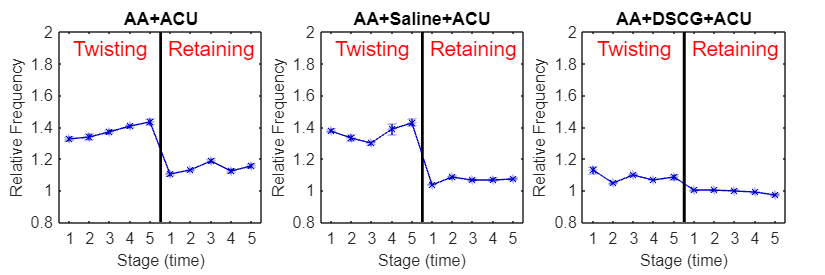

folders = {'acu','saline','dscg'};
titles = {'AA+ACU','AA+Saline+ACU','AA+DSCG+ACU'};
fig = figure(1); clf; set(gcf,'position',[0,0,250*length(folders),250]);
tiledlayout(1,length(folders),"TileSpacing","compact","Padding","compact");
for k = 1:length(folders)
    nexttile(k);
    folder = folders{k};
    FRfile = sprintf('./source_data/%s_FR_original.mat',folder);
    load(FRfile); FRnorm = FR; FRbase = mean( FR(:,1:60),2 ); 
    [n,nT] = size(FR);
    for i = 1:n 
        FRnorm(i,:) = FRnorm(i,:)/FRbase(i);
    end
    % 
    idx = 150+[1:60]; idx = reshape(idx,6,10);
    idx_twist = idx(:,1:2:end); idx_retain= idx(:,2:2:end);
    FRtwist = FR(:,idx_twist(:)); FRretain= FR(:,idx_retain(:)); 
    FRtwist_norm = FRnorm(:,idx_twist(:)); FRretain_norm = FRnorm(:,idx_retain(:));

    [FRtwist_n_mean, FRtwist_n_se, FRretain_n_mean, FRretain_n_se] = deal(zeros(5,1));
    method = 3;
    for i = 1:5
        twist_i = 6*(i-1)+[1:6]; retain_i = 6*(i-1)+[1:6];
        FRtwist_norm_i = FRtwist_norm(:,twist_i);
        FRretain_norm_i = FRretain_norm(:,retain_i);
        [m,sd,se] = fun_mean_se(FRtwist_norm_i,method);  FRtwist_n_mean(i)=m;  FRtwist_n_se(i) = se;
        [m,sd,se] = fun_mean_se(FRretain_norm_i,method); FRretain_n_mean(i)=m; FRretain_n_se(i) = se;
    end
    mean_y = [FRtwist_n_mean; FRretain_n_mean];
    se_y = [FRtwist_n_se; FRretain_n_se];
    errorbar(1:length(mean_y),mean_y,se_y,'*-','color',[0,0,0.8]); hold on;
    set(gca,'xlim',[0.5,10.5],'ylim',[0.8,2]); set(gca,'fontsize',11);
    xlabel('Stage (time)', 'FontSize',11); ylabel('Relative Frequency','fontsize',11);
    title(titles{k});
    plot([5.5,5.5],[0.5,2],'k-','linewidth',2);
    text( 3,1.9,'Twisting', 'FontSize',14,'HorizontalAlignment','center','color','r' );
    text( 8,1.9,'Retaining','FontSize',14,'HorizontalAlignment','center','color','r' );
    set(gca,'xtick',[1:1:10],'xticklabel',[1 2 3 4 5 1 2 3 4 5],'ytick',[0.8:0.2:2.0]);
end

## 5. Analysis of ISI

We classified the 1/ISI (inter-spike interval) frequencies into low, medium, and high bands based on the probability density function derived from histograms. For each nerve, firing events were divided into three equal segments according to the distribution, with two threshold frequencies established to delineate the respective bands. This methodology was specifically designed to enhance the detection of experimental phase-dependent effects on 1/ISI frequencies while minimizing confounding influences from inter-individual variability. The approach was applied to both baseline and stabilization phases, as illustrated in the following example.

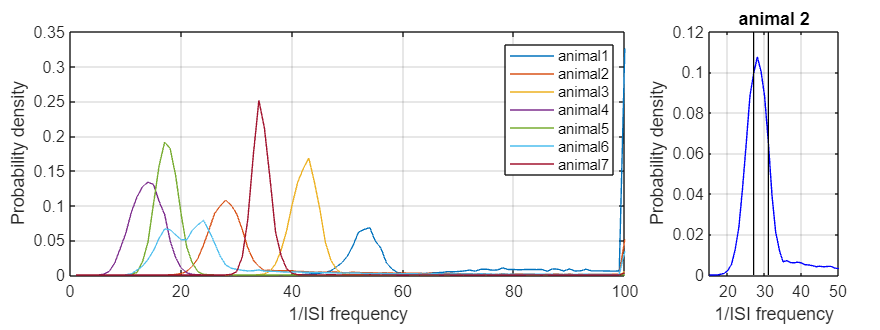

FRfile = './source_data/ACU_FR_original.mat'; 
load(FRfile); 
figure(1); set(gcf,'position',[0,0,800,300]);
tiledlayout(1,4,"TileSpacing","compact","Padding","compact");
nexttile(1,[1,3]);
for animal = 1:7
    spikeloc = SpikeLoc{animal}; fs = 20000;
    % calculate the ISIf 
    ISIf = fs./diff(spikeloc);
    ISIft = spikeloc(1:end-1)/fs/60; % in minutes
    ISIf_ = ISIf(ISIft<25); % baseline and stabilization stages
    bins = [1:100];
    dist = hist(ISIf_,bins);
    plot(bins, dist/sum(dist),'-'); hold on; grid on;
    if animal==2
        dist2 = dist;
    end
end
xlabel('1/ISI frequency'); ylabel('Probability density'); set(gca,'fontsize',11);
legend({'animal1','animal2','animal3','animal4','animal5','animal6','animal7'});
nexttile(4); y = dist2/sum(dist2);
plot(bins,y,'b-'); xlabel('1/ISI frequency'); ylabel('Probability density'); title('animal 2');
set(gca,'xlim',[15,50]); grid on; hold on; set(gca,'fontsize',11);
cy = cumsum(y); tmp1 = find(cy>=1/3); tmp2 = find(cy>=2/3);
f1 = bins(tmp1(1)); f2 = bins(tmp2(1)); 
plot([f1,f1],get(gca,'ylim'),'k-'); plot([f2,f2],get(gca,'ylim'),'k-'); 

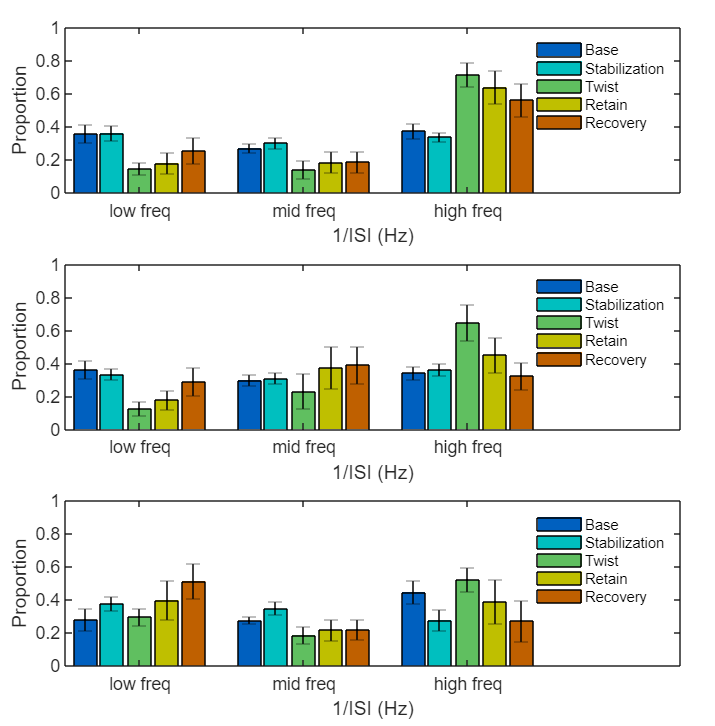

folders = {'ACU','SALINE','DSCG'};
figure(1); set(gcf,'position',[0,0,650,220*length(folders)]);
tiledlayout(length(folders),1,"TileSpacing","Compact","Padding","Compact");
for kk = 1:length(folders)
    folder = folders{kk};
    nexttile(kk);
    FRfile = sprintf('./source_data/%s_FR_original.mat',folder);
    load(FRfile); fs = 20000; 
    ISInumber = zeros(7,5,3); % 7 animals, 5 stages, 3 bands
    for animal = 1:7
        spikeloc = SpikeLoc{animal};
        ISI = diff(spikeloc)/fs;
        ISIf = 1./ISI;
        ISIft = spikeloc(1:end-1)/fs/60; % in minutes 
        stage_base  = (ISIft<=10);
        stage_stab  = (ISIft>10)&(ISIft<=25);
        stage_twist = (ISIft>25)&(ISIft<=35)&(mod(floor(ISIft-25),2)==0);
        stage_retain= (ISIft>25)&(ISIft<=35)&(mod(floor(ISIft-25),2)~=0);
        stage_reco  = (ISIft>35);
        stage_filter = {stage_base,stage_stab,stage_twist,stage_retain,stage_reco};
        
        % determine the frequency threshold 
        ISIf_ = ISIf(ISIft<25); % baseline and stabilization stages
        bins = [1:100]; dist = hist(ISIf_,bins); y = dist/sum(dist);
        cy = cumsum(y); tmp1 = find(cy>=1/3); tmp2 = find(cy>=2/3); 
        f1 = bins(tmp1(1)); f2 = bins(tmp2(1)); 
        % 
        fre = [f1,f2];
        band_low = (ISIf<=fre(1)); 
        band_mid = (ISIf>fre(1))&(ISIf<fre(2));
        band_high= (ISIf>=fre(2));
        band_filter = {band_low, band_mid, band_high};
        for ii = 1:length(stage_filter) 
            for jj = 1:length(band_filter)
                ISInumber(animal,ii,jj) = sum( stage_filter{ii} & band_filter{jj} );
            end
        end
    end
    ISIprop = 0*ISInumber;
    for animal = 1:7
        ISIn = reshape(ISInumber(animal,:,:),5,3);
        ISIp = ISIn*0;
        sum_ISIn = sum(ISIn,2);
        for stage = 1:5
            ISIp(stage,:) = ISIn(stage,:)/sum_ISIn(stage);
        end
        ISIprop(animal,:,:) = ISIp;
    end
    colors = jet(5)*0.75; 
    ISIp_mean = reshape( mean(ISIprop,1), 5, 3 );
    ISIp_se = reshape( std(ISIprop,[],1),5,3) / sqrt(7);
    % plot the results
    ISIp_mean = ISIp_mean(:);
    ISIp_se = ISIp_se(:);
    x = [0.67, 0.83, 1, 1.167, 1.33, 1.67, 1.83, 2.0, 2.167, 2.33, 2.67, 2.83, 3.0, 3.167, 3.33];
    for k = 1:5
        b(k) = bar(x(k:5:end),ISIp_mean(k:5:end),'barwidth',0.14,'facecolor',colors(k,:)); hold on;
    end
    errorbar(x,ISIp_mean,ISIp_se,'k.','capsize',10); set(gca,'xlim',[0.55,4.3],'ylim',[0,1]);
    % title(folder); 
    xlabel('1/ISI (Hz)'); ylabel('Proportion');
    set(gca,'xtick',[1,2,3],'xticklabel',{'low freq','mid freq','high freq'},'fontsize',12);
    set(gca,'ytick',[0:0.2:1.0]);
    legend(b,{'Base','Stabilization','Twist','Retain','Recovery'},'location','northeast',...
        'FontSize',10,'box','off');
    % 
    file = sprintf('source_data/%s_ISIp.mat',folder);
    save(file,'ISIprop'); 
end

% the table 
folders = {'ACU','SALINE','DSCG'};
ISIp = zeros(3,7,5,3); % group, animal, stage, frequency_band
for fidx = 1:length(folders)
    load(['source_data\',folders{fidx},'_ISIp.mat']);
    ISIp(fidx,:,:,:) = ISIprop;
end
% 
output = '';
fband_text = {'low-frequency','mid-frequency','high-frequency'};
group_text = {'AA+ACU','AA+Saline+ACU','AA+DSCG+ACU'};
output = [output, sprintf('%15s |%13s|%13s|%13s|%13s|%13s|\n', ...
    'Stage','Base','Stabilization','Twisting','Retaining','Recovery')];
sep = repmat('-',1,35);
for fband = 1:3
    output = [output, sprintf('%s %15s %s\n', sep,fband_text{fband},sep)];
    for group = 1:3
        output = [output, sprintf('%15s |', group_text{group})];
        for stage = 1:5
            tmp = ISIp(group,:,stage,fband);
            output = [output, sprintf(' %3.2f ± %3.2f |',mean(tmp),std(tmp)/sqrt(length(tmp)))];
        end
        output = [output,newline];
    end
end
fprintf(1,'1/ISI proportions report\n\n'); disp(output); % the result for table 2

1/ISI proportions report

          Stage |         Base|Stabilization|     Twisting|    Retaining|     Recovery|
-----------------------------------   low-frequency -----------------------------------
         AA+ACU | 0.36 ± 0.05 | 0.36 ± 0.05 | 0.15 ± 0.03 | 0.18 ± 0.07 | 0.25 ± 0.08 |
  AA+Saline+ACU | 0.36 ± 0.05 | 0.33 ± 0.03 | 0.13 ± 0.04 | 0.18 ± 0.06 | 0.29 ± 0.09 |
    AA+DSCG+ACU | 0.28 ± 0.07 | 0.38 ± 0.04 | 0.30 ± 0.05 | 0.40 ± 0.12 | 0.51 ± 0.11 |
-----------------------------------   mid-frequency -----------------------------------
         AA+ACU | 0.27 ± 0.03 | 0.30 ± 0.03 | 0.14 ± 0.05 | 0.18 ± 0.06 | 0.19 ± 0.06 |
  AA+Saline+ACU | 0.30 ± 0.03 | 0.31 ± 0.03 | 0.23 ± 0.11 | 0.37 ± 0.13 | 0.39 ± 0.11 |
    AA+DSCG+ACU | 0.27 ± 0.02 | 0.35 ± 0.04 | 0.18 ± 0.05 | 0.22 ± 0.06 | 0.22 ± 0.06 |
-----------------------------------  high-frequency -----------------------------------
         AA+ACU | 0.37 ± 0.05 | 0.34 ± 0.03 | 0.72 ± 0.07 | 0.64 ± 0.10 | 0.56 ± 0.10 |
  AA+S

The low-, medium-, and high-frequency 1/ISI values for each phase were calculated as changes relative to the baseline firing rate, followed by repeated-measures ANOVA (rm-ANOVA).

group_names = {'ACU', 'SALINE', 'DSCG'};
band_names = {'Low', 'Mid', 'High'};
stage_names = {'Base', 'Stabilization', 'Twisting', 'Retaining', 'Recovery'};
output = sprintf('%15s |%13s|%13s|%13s|%13s|\n', ...
    'Groups','Stabilization','Twisting','Retaining','Recovery');
Pvalues = zeros(3,3,4); % group,band,stage
for fband = 1:3
    output = [output, sprintf('%s %15s %s\n', sep,fband_text{fband},sep)];
    for group = 1:3
        output = [output, sprintf('%15s |', group_text{group})];
        group_band_data = squeeze(ISIp(group, :, :, fband)); % [7 animals × 5 stages]
        data_matrix = group_band_data;
        rm_table = array2table(data_matrix, 'VariableNames', stage_names);
        rm_table.Animal = (1:size(data_matrix, 1))';
        within_factor = table([1 2 3 4 5]', 'VariableNames', {'Stage'});
        rm = fitrm(rm_table, 'Base-Recovery ~ 1', 'WithinDesign', within_factor);
        mc = multcompare(rm, 'Stage', 'comparisonType','lsd');
        mc = mc{:,:};
        for stage = 2:5
            pp = find( (mc(:,1)==1) & (mc(:,2)==stage) ); 
            pvalue = mc(pp,5);
            output = [output, sprintf(' %11.5f |',pvalue)];
            Pvalues(group,fband,stage-1) = pvalue;
        end
        output = [output,newline];
    end
end
fprintf(1,'P-values of 1/ISI proportion (Other stages vs Base) \n\n'); disp(output);

P-values of 1/ISI proportion (Other stages vs Base) 

         Groups |Stabilization|     Twisting|    Retaining|     Recovery|
-----------------------------------   low-frequency -----------------------------------
         AA+ACU |     0.97304 |     0.04937 |     0.15329 |     0.45168 |
  AA+Saline+ACU |     0.71477 |     0.01699 |     0.07748 |     0.52461 |
    AA+DSCG+ACU |     0.38714 |     0.88632 |     0.52282 |     0.19289 |
-----------------------------------   mid-frequency -----------------------------------
         AA+ACU |     0.47077 |     0.02183 |     0.17990 |     0.19487 |
  AA+Saline+ACU |     0.57660 |     0.54599 |     0.56893 |     0.41102 |
    AA+DSCG+ACU |     0.11576 |     0.15433 |     0.37639 |     0.31116 |
-----------------------------------  high-frequency -----------------------------------
         AA+ACU |     0.61683 |     0.00958 |     0.06614 |     0.21670 |
  AA+Saline+ACU |     0.81209 |     0.04956 |     0.39114 |     0.84384 |
    AA+DSCG+ACU 

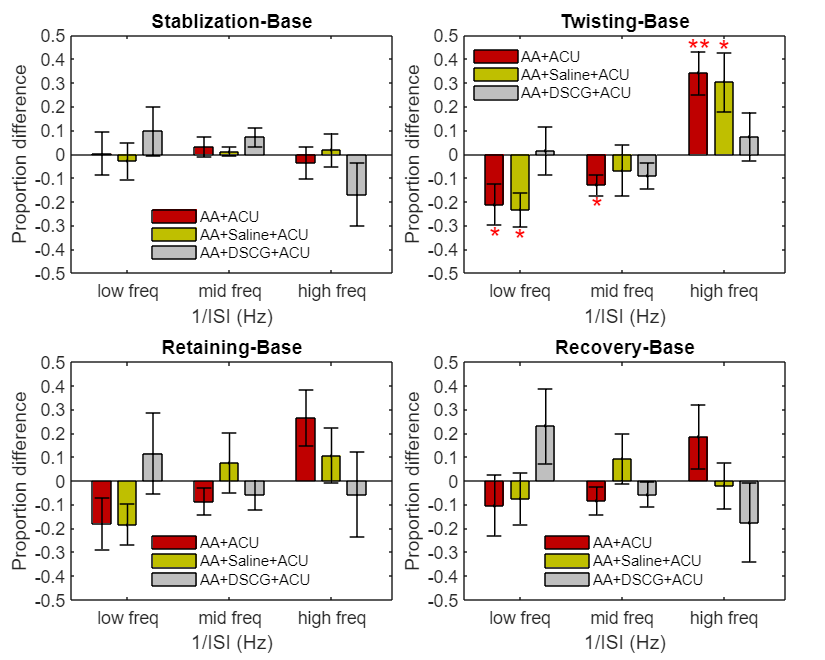

folders = {'ACU','SALINE','DSCG'};
ISIp = zeros(3,7,5,3); % group, animal, stage, frequency_band
for fidx = 1:length(folders)
    load(['source_data\',folders{fidx},'_ISIp.mat']);
    ISIp(fidx,:,:,:) = ISIprop;
end
dI = zeros(3,7,4,3); % group, animal, stage, frequency_band
for stage = 1:4
    dI(:,:,stage,:) = ISIp(:,:,stage+1,:)-ISIp(:,:,1,:);
end
% to plot the result 
figure(2); set(gcf,'position',[0,0,750,600]);
tiledlayout(2,2,"TileSpacing","compact","Padding","compact");
title_stage = {'Stablization-Base','Twisting-Base','Retaining-Base','Recovery-Base'};
for stage = 1:4
    dIstage = dI(:,:,stage,:);
    d_mean = squeeze(mean(dIstage,2)); % group, frequency
    d_se = squeeze( std(dIstage,[],2)/sqrt(size(dIstage,2)) );
    nexttile(stage);
    d = 0.25; colors = hot(3)*0.75; 
    x = [linspace(1-d,1+d,3),linspace(2-d,2+d,3),linspace(3-d,3+d,3)];
    barhandle = [];
    for i = 1:3 % group
        barhandle(i) = bar(x(i:3:end),d_mean(i,:), 'barwidth',0.18,...
            'facecolor',colors(i,:)); hold on;
        errorbar(x(i:3:end),d_mean(i,:),d_se(i,:),'k.','capsize',10,'linewidth',1);
    end
    % cope with Pvalues
    psigs = {'','*','**','***','****'};
    for i = 1:3 % group
        for j = 1:3 % fband
            pvalue = Pvalues(i,j,stage); 
            p_threshold = [0.05,0.01,0.001,0.0001,0];
            tmp = find(pvalue>p_threshold); tmp = tmp(1);
            psig = psigs{tmp};
            mean_value = mean(dI(i,:,stage,j));
            se_value = std(dI(i,:,stage,j))/sqrt(size(dI,2));
            if mean_value>0
                yloc = mean_value+se_value+0.01;
            else
                yloc = mean_value-se_value-0.05;
            end
            text(x(3*(j-1)+i),yloc,psig,'fontname','arial','fontsize',20,'color','r',...
                'HorizontalAlignment','center','VerticalAlignment','middle');
        end
    end
    %
    title(title_stage{stage});  set(gca,'fontsize',11, 'ytick', [-0.5:0.1:0.5]);
    set(gca,'xlim',[0.45,3.6],'ylim',[-0.5,0.5]);
    xlabel('1/ISI (Hz)','fontsize',12); ylabel('Proportion difference','fontsize',12);
    set(gca,'xtick',[1,2,3],'xticklabel',{'low freq','mid freq','high freq'},'fontsize',12);
    legend(barhandle,{'AA+ACU','AA+Saline+ACU','AA+DSCG+ACU'},...
        'FontSize',10,'box','off','location','best');  
end